# Radiation Therapy 

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

- Define the optimization problem, give it a description `"Radiation Therapy Optimization"` and store it in `prob`.

- Define the 8-by-1 optimization variable for the intensities of each beamlet  and include a lowerbound of zero. Store the variables in an optimization variable vector `I`

prob = optimproblem("Description","Radiation Therapy Optimization")

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [0×0 struct] containing 0 OptimizationVariables
         Objective: [0×0 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  No problem defined.


I = optimvar("I",8,"LowerBound",0)

I =   8×1 OptimizationVariable array with properties:

  Array-wide properties:
          Name: 'I'
          Type: 'continuous'
    IndexNames: {{}  {}}

  Elementwise properties:
    LowerBound: [8×1 double]
    UpperBound: [8×1 double]

  See variables with show.
  See bounds with showbounds.


## Task 2

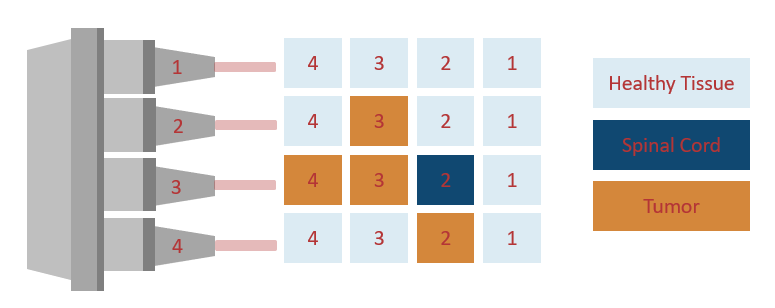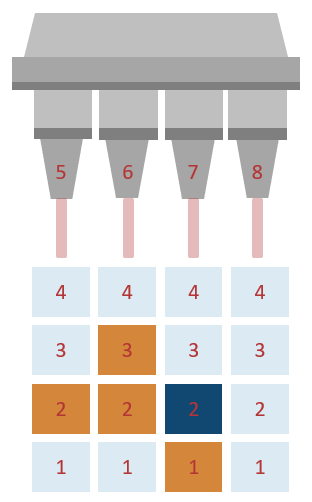

The cell response to radiation is represented by the  numbers in the grid. The dose delivered to any cell in the grid is  computed by multiplying the cell response and the intensity of the  beamlet passing through the cell.

You just saw that adding the  numbers in the light or blue cells give the total healthy cell response  for each of the rows in the grid. These are the rows impacted by  beamlets 1-4. Now you must do the same for each of the columns, which  are impacted by beamlets 5-8.  

Task

Compute the total radiation dose delivered to the healthy tissue and the spinal cord following the steps below:  

- Store the total cell response for the healthy tissue and spinal cord cells in a 1-by-8 array `d`, The first four elements should correspond to the cell response of the  rows as shown below. The last four elements correspond to the cell  response of the columns. These are obtained by adding the numbers in the light and dark blue cells down each column. Use the image under Task 2  in the live script for reference. 

- Multiply the cell responses `d` by the radiation intensities `I` to obtain the total radiation dose delivered. Store the result in a variable `D`.

d=[10 7 3 8 8 5 9 10]

d =     10     7     3     8     8     5     9    10


D=d*I

D =   Linear OptimizationExpression

    10*I(1) + 7*I(2) + 3*I(3) + 8*I(4) + 8*I(5) + 5*I(6) + 9*I(7) + 10*I(8)


## Task 3

The objective function is the sum of all of the doses delivered to the healthy tissue and spinal cord. 

Because you defined the radiation intensities as an 8-by-1 column  vector and the cell responses as a 1-by-8 row vector, the sum was  performed for you during the matrix multiplication. 

Task

Store the total radiation dose `D` in the `Objective` field of your optimization problem.

prob.Objective=sum(D)

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [0×0 struct] containing 0 OptimizationConstraints

  See problem formulation with show.


## Task 4

The spinal cord should not receive a dose of more than 5 units. This translates to the constraint:  

2I3+2I7≤5, where  I3 and  I7, are the intensities of the third and seventh beamlets, respectively. 

Task

Store this inequality constraint in your optimization problem. Give the constraint the name `spinal`

prob.Constraints.spinal=2*I(3)+2*I(7)<=5

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 1 OptimizationConstraint

  See problem formulation with show.


## Task 5

Every tumor cell needs to receive a sufficiently lethal dose of at least 7 units. Since there are four tumor cells containing cancerous  material, this corresponds to four inequality constraints as indicated  below. 

 Whenever two beamlets intersect on an orange tumor cell, a  constraint must be defined. Each constraint is imposed on the sum of the products of the intersecting beams and the dosage, which is represented by the numbers adjacent to each tumor cell. 

The constraints are: 

A:  

3I2+3I6≥7

B:  

3I3+2I6≥7

C:  

4I3+2I5≥7

and 

D:  

2I4+I7≥7

prob.Constraints.A=3*I(2)+3*I(6)>=7

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 2 OptimizationConstraints

  See problem formulation with show.


prob.Constraints.B=3*I(3)+2*I(6)>=7

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 3 OptimizationConstraints

  See problem formulation with show.


prob.Constraints.C=4*I(3)+2*I(5)>=7

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 4 OptimizationConstraints

  See problem formulation with show.


prob.Constraints.D=2*I(4)+I(7)>=7

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 5 OptimizationConstraints

  See problem formulation with show.


## Task 6

Solve the optimization problem. This time, only include a single output and name it `sol`. Remember, since this is a linear objective function you do not need to include an initial guess.

sol=solve(prob)

Solving problem using linprog.

Optimal solution found.



sol = struct with fields:
    I: [8×1 double]


## Task 7

Create a bar graph of the optimal beamlet intensities stored in `sol`.

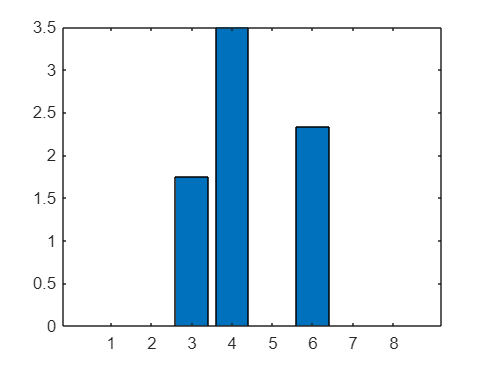

bar(sol.I)

## Task 8

Evaluate the dose delivered to the spinal cord at the optimal solution: 

- Define an optimization expression for the dose delivered to the spinal cord.  Note that you can use the same expression from Task 4.

- Check to see if the optimal solution satisfied the constraint `spinal`. Store the result in a variable named `check`. You may want to leave off the semi-colon to display the result.

prob.Constraints.spinal=2*I(3)+2*I(7)<=5

prob =   OptimizationProblem with properties:

       Description: 'Radiation Therapy Optimization'
    ObjectiveSense: 'minimize'
         Variables: [1×1 struct] containing 1 OptimizationVariable
         Objective: [1×1 OptimizationExpression]
       Constraints: [1×1 struct] containing 5 OptimizationConstraints

  See problem formulation with show.


check=evaluate(2*I(3)+2*I(7),sol)

check = 3.5000

## Further Practice

Notice that the optimal radiation intensity is zero for beamlets 1, 2,  7, and 8. This is due to the fact that they encounter a lot of healthy  tissue that is highly susceptible to radiation.

 Also, we wanted the dose delivered to the spinal cord to be less than 5, and our result was 3.5, which is even better. 

Now you can visualize the doses delivered to each cell using the following code.

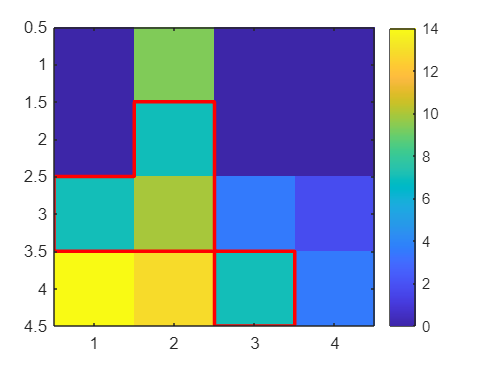

verticalBeamTable = [4 4 4 4; 3 3 3 3; 2 2 2 2; 1 1 1 1];
horizontalBeamTable = [4 3 2 1; 4 3 2 1; 4 3 2 1; 4 3 2 1];

verticalIntensity = [0 2.33 0 0];
horizontalIntensity = [0 0 1.75 3.5];

horizontalDose = horizontalBeamTable .* horizontalIntensity';
verticalDose = verticalBeamTable .* verticalIntensity;

Doses = horizontalDose + verticalDose;

imagesc(Doses)
hold on
plot([.5 .5 1.5 1.5 2.5 2.5 3.5 3.5 2.5 2.5 0.5],...
    [3.5 2.5 2.5 1.5 1.5 3.5 3.5 4.5 4.5 3.5 3.5], 'r-', "LineWidth",2)
hold off
colorbar